# 9주차 — 주파수응답: 사인을 넣어 보면

**제어시스템설계** · 충남대학교 자율운항시스템공학과

**참고자료 — 먼저 볼 것**

아래 다섯 과목은 **이 강의의 담당교수가 직접 한 강의**입니다. 기초부터 대학원 과정까지 이어지므로 부족한 곳부터 보면 됩니다. 이 강의에서 쓰는 기호와 유도는 모두 그 안에서 자세히 다룹니다.

**MATLAB 이나 Simulink 가 아직 익숙하지 않다면** 실습에 들어가기 전에 아래를 먼저 하십시오. 무료이고 각각 몇 시간이면 끝납니다.

지난 주까지는 **시간**으로 봤습니다. 계단을 넣고 얼마나 빨리, 얼마나 흔들리며 따라오는지를 봤습니다.

오늘부터는 **주파수**로 봅니다. 사인을 넣고 크기와 위상이 어떻게 달라지는지 봅니다.

왜 굳이 다른 눈으로 보는가 — 세 가지 이유가 있습니다.

- **모델이 없어도 잴 수 있다.** 사인파를 넣어 보면 되니까 실험만으로 얻는다

- **곱셈이 덧셈이 된다.** 여러 블록이 이어진 시스템을 손으로 그릴 수 있다

- **여유를 숫자로 준다.** 모델이 조금 틀려도 버티는지를 10주차에서 본다

if isempty(which('plant_msd'))   % 경로가 아직 등록 안 되었으면 알아서 잡는다
    p_ = pwd;
    if ~isempty(mfilename('fullpath')), p_ = fileparts(mfilename('fullpath')); end
    for k_ = 1:4
        if isfile(fullfile(p_,'setup_path.m')), run(fullfile(p_,'setup_path.m')); break; end
        p_ = fileparts(p_);
    end
    clear p_ k_
end
clc; close all;
s = tf('s');

## 0-0. 오늘 돌려 볼 파일

강의노트를 읽다가 **직접 값을 바꿔 보고 싶을 때** 여는 파일들입니다. 모두 `W09_Bode` 폴더 안에 있습니다.

오늘 처음 쓰는 도우미 함수 두 개도 `common/` 에 있습니다.

실행하는 법 — 파일을 열고 절 안에서 `Ctrl+Enter` 를 누르면 그 절만 돕니다. 전체는 `F5` 입니다. 처음 한 번은 `setup_path` 를 먼저 실행하십시오.

이 강의노트의 **그림은 전부** `make_figures.m` 이 만들어 `common/figures/` 에 넣어 둔 것입니다. 그림마다 어느 함수가 만들었는지 아래에 적어 두었습니다.

## 0. 오늘 한 장 요약

오늘 배우는 것을 한 문장으로 적으면 이렇습니다.

**선형 시불변 시스템에 사인을 넣으면 같은 주파수의 사인이 나온다. 달라지는 것은 크기와 위상뿐이고, 그 둘을 주파수마다 모은 것이 보드 선도다.**

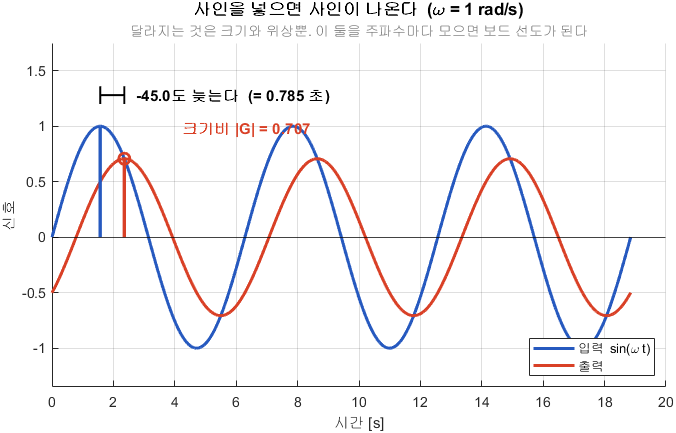

사인을 넣으면 크기와 위상만 달라진 사인이 나온다

**그림 파일** `w09_sine_io.png` — `common/dg_sine_io.m` 의 `dg_sine_io` · 다시 만들려면 `make_figures('w09_sine_io')`

**만드는 곳** — `common/dg_sine_io.m` (`make_figures('w09_sine_io')`). 명령창에서 `dg_sine_io(3)` 처럼 다른 주파수로 직접 불러도 됩니다 **직접 바꿔 보려면** — `W09_01_sine_to_bode.m` 의 **1절**에서 `w` 를 $0.1$, $1$, $10$ 으로 바꿔 실행

그림 해석 — **이 표를 그대로 읽으면 오늘 0절 설명이 됩니다**

$|G| = 0.707$ 과 위상 $-45^\circ$ — 이 **두 숫자**가 주파수 $\omega=1$ 에서 이 시스템을 완전히 설명합니다. 주파수를 바꿔 가며 이 두 숫자를 모으면 그것이 보드 선도입니다.

오늘의 계단

- **1~2절** 사인을 넣으면 무슨 일이 생기는가

- **3절** 크기와 위상을 어떻게 재는가

- **4절** 보드 선도 — 왜 dB 와 로그축인가

- **5절** 손으로 그리는 법 (네 조각과 점근선)

- **6절** 2차 항의 봉우리

- **7절** Simulink 로 직접 재 보기

## 0-1. 가장 작은 예부터

파라미터가 하나뿐인 시스템으로 시작합니다.


$$G(s) = \frac{1}{s+1}$$


여기에 $\omega = 1$ 인 사인을 넣으면 어떻게 되는지 봅니다. 손으로 계산할 수 있습니다. $s$ 자리에 $j\omega = j$ 를 넣기만 하면 됩니다.


$$G(j1) = \frac{1}{j+1}$$


크기는 분모의 크기로 나누면 되고


$$|G(j1)| = \frac{1}{|1+j|} = \frac{1}{\sqrt{2}} \approx 0.707$$


위상은 분모의 각을 빼면 됩니다.


$$\angle G(j1) = -\angle(1+j) = -45^\circ$$


즉 **크기는 0.707 배로 줄고, 45도 늦게 따라온다** 는 뜻입니다. 정말 그런지 코드로 확인합니다.

G0 = 1/(s+1);
w0 = 1;
G0jw = freqresp(G0, w0);
fprintf('=== 손계산과 대조 ===\n');
fprintf('  손계산  : 크기 %.4f , 위상 %.1f 도\n', 1/sqrt(2), -45);
fprintf('  MATLAB  : 크기 %.4f , 위상 %.1f 도\n\n', abs(G0jw), rad2deg(angle(G0jw)));
t = (0:0.02:20)';
u = sin(w0*t);
y = lsim(G0, u, t);
plot(t, u, 'LineWidth', 2); hold on;
plot(t, y, 'LineWidth', 2); grid on;
xlabel('시간 [s]'); ylabel('신호');
legend('입력 sin(t)', '출력', 'Location','southeast');
title('0.707 배로 줄고 45도 늦는다');

## 0-2. 45도가 얼마나 늦는 것인가

위상은 각도지만 실제로는 **시간지연**입니다. 바꾸는 법은 간단합니다.


$$\text{시간지연} = \frac{\text{위상}[\mathrm{rad}]}{\omega}$$


위 예에서 $45^\circ = \pi/4$ 라디안이고 $\omega = 1$ 이므로 $\pi/4 \approx 0.785$ 초 늦습니다.

**주의할 점** — 같은 위상이라도 주파수가 다르면 시간지연이 다릅니다. 주파수가 두 배면 같은 각도라도 지연은 절반입니다.

fprintf('=== 같은 45도라도 주파수에 따라 다르다 ===\n');
fprintf('     w[rad s^-1]    45도가 뜻하는 시간지연[s]\n');
fprintf('    ------------  --------------------------\n');
for wq = [0.5 1 2 10]
    fprintf('    %12.1f  %26.4f\n', wq, (pi/4)/wq);
end
fprintf('\n');

## 1. 왜 사인인가

계단이나 임펄스가 아니라 왜 하필 사인인가.

이유는 하나입니다. **선형 시불변 시스템에서 사인만이 모양을 유지합니다.**

- 계단을 넣으면 출력은 계단이 아니다 (지수함수가 섞인 곡선이 나온다)

- 임펄스를 넣으면 출력은 임펄스가 아니다

- **사인을 넣으면 출력도 사인이다.** 크기와 위상만 달라진다

모양이 유지되므로 "무엇이 달라졌는가" 를 숫자 **두 개**로 요약할 수 있습니다. 그 두 숫자가 크기비와 위상차입니다.

그리고 푸리에가 알려 준 대로 어떤 신호든 사인의 합으로 쓸 수 있으므로, 사인 하나에 대한 답을 알면 **모든 신호에 대한 답을 아는 것**입니다.

## 2. 정말 사인이 나오는가 — 유도

말로만 하지 말고 식으로 확인합니다.

입력이 $u(t) = \sin(\omega t)$ 이면 라플라스 변환은


$$U(s) = \frac{\omega}{s^2 + \omega^2} = \frac{\omega}{(s-j\omega)(s+j\omega)}$$


출력은 $Y(s) = G(s)U(s)$ 이므로 부분분수로 쪼개면 이렇게 됩니다.


$$Y(s) = \frac{A}{s - j\omega} + \frac{\bar{A}}{s + j\omega} + (\text{G 의 극점에서 오는 항들})$$


오른쪽 괄호의 항들은 $G$ 의 극점이 좌반면에 있으면 **시간이 지나면 사라집니다.** 남는 것은 앞의 두 항뿐이고, 이것이 정상상태 응답입니다.

계수 $A$ 를 구하면


$$A = \left. (s - j\omega)\,\frac{G(s)\,\omega}{(s-j\omega)(s+j\omega)} \right|_{s = j\omega} = \frac{G(j\omega)}{2j}$$


이것을 되돌리면 결국


$$y_{ss}(t) = |G(j\omega)|\,\sin\left(\omega t + \angle G(j\omega)\right)$$


**결론** — 정상상태 사인응답의 크기비와 위상차는 그냥 $G(s)$ 에 $s = j\omega$ 를 넣은 값입니다. 외울 것도 없습니다.

## 2-1. 앞 주차와 이어 보기

같은 이야기가 계속 반복되고 있습니다.

- **계단**의 정상상태 $\rightarrow$ $G(0)$ 을 본다 (5주차 `dcgain`)

- **사인**의 정상상태 $\rightarrow$ $G(j\omega)$ 를 본다 (오늘)

둘 다 "입력의 극점 자리에 $s$ 를 넣는다" 는 같은 규칙입니다. 계단의 극점은 $s = 0$, 사인의 극점은 $s = \pm j\omega$ 이기 때문입니다.

## 3. 크기와 위상을 어떻게 재는가

실험으로 잰다면 두 가지 방법이 있습니다.

- **눈으로** — 진폭을 자로 재고, 꼭짓점이 얼마나 늦는지 본다. 직관적이지만 잡음이 있으면 부정확하다

- **계산으로** — 신호에 $e^{-j\omega t}$ 를 곱해 적분한다. 푸리에 계수를 구하는 것과 같고, 잡음에 강해 실무에서 이 방법을 쓴다

**반드시 지킬 것 하나** — 과도응답이 사라진 뒤에 재야 합니다. 처음 몇 주기는 $G$ 의 극점에서 오는 항이 섞여 있어 값이 틀립니다.

아래는 여러 주파수에서 실제로 재서 `bode` 곡선 위에 얹어 본 결과입니다.

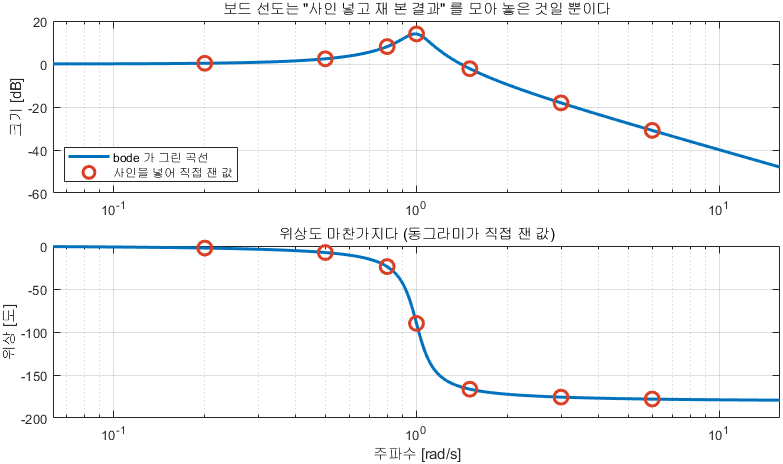

직접 잰 값(동그라미)이 bode 곡선 위에 정확히 놓인다

**그림 파일** `w09_measure.png` — `make_figures.m` 의 `fig_sine_measure` · 다시 만들려면 `make_figures('w09_measure')`

**만드는 곳** — `make_figures.m` 의 `fig_sine_measure` **직접 해 보려면** — `W09_01_sine_to_bode.m` 을 실행하면 `freq_scan` 이 주파수마다 사인을 넣어 재는 과정을 표로 찍어 줍니다

그림 해석

**위아래 두 장이 한 세트입니다.** 크기만 보면 절반만 본 것입니다. 10주차의 안정여유는 이 **아래 그림**에서 나옵니다.

## 3-1. `bode` — 주파수응답을 그리는 명령

**오늘의 새 명령입니다.**

명령 정리

- **원리** — 주파수 $\omega$ 를 훑으며 $G(j\omega)$ 를 계산해 크기와 위상을 그린다

- **입력** — 전달함수. 주파수 벡터를 두 번째 인자로 줄 수도 있다

- **출력** — 출력을 받지 않고 부르면 그림. 출력을 받으면 `[mag, phase, w]` 숫자

주의 세 가지

- 출력으로 받은 `mag` 는 **dB 가 아니라 배율**이다. dB 로 보려면 `20*log10(mag)` 를 직접 해야 한다

- `mag` 와 `phase` 는 3차원 배열로 나온다. `squeeze` 로 눌러야 그릴 수 있다

- 위상은 $\pm 180^\circ$ 를 넘나들며 튈 수 있다. 필요하면 `unwrap` 을 쓴다

G1 = 10/(s*(s+1));
[mg, pg, wg] = bode(G1);
mg = squeeze(mg);  pg = squeeze(pg);
fprintf('=== bode 의 출력 ===\n');
fprintf('  주파수 점 %d 개\n', numel(wg));
fprintf('     w[rad s^-1]    mag(배율)    dB       위상[도]\n');
fprintf('    ------------  -----------  -------  ---------\n');
for i = round(linspace(1, numel(wg), 6))
    fprintf('    %12.4f  %11.4f  %7.2f  %9.2f\n', ...
            wg(i), mg(i), 20*log10(mg(i)), pg(i));
end
fprintf('\n');
bode(G1); grid on;
title('bode 로 그린 주파수응답');

## 4. 왜 dB 이고 왜 로그축인가

두 가지 이유가 있고, 둘 다 실용적인 이유입니다.

**이유 하나 — 곱셈이 덧셈이 된다**


$$20\log_{10}|G_1 G_2| = 20\log_{10}|G_1| + 20\log_{10}|G_2|$$


전달함수는 대개 인수들의 곱입니다. 로그를 취하면 합이 되므로 **조각마다 따로 그린 뒤 세로로 더하면** 전체가 됩니다. 5절의 손작도가 가능한 것이 순전히 이 성질 덕분입니다.

**이유 둘 — 넓은 범위를 한 그림에**

크기가 $1000$ 배 차이 나도 dB 로는 $60$ 차이일 뿐입니다. 주파수도 마찬가지라서 로그축을 씁니다.

fprintf('=== 외워 두면 편한 dB 값 ===\n');
tbl = {0.01,'백분의 일'; 0.1,'십분의 일'; 0.5,'절반'; ...
       1/sqrt(2),'1/sqrt(2)'; 1,'그대로'; 2,'두 배'; 10,'열 배'; 100,'백 배'};
fprintf('     배율        dB      설명\n');
fprintf('    --------  --------  ----------\n');
for i = 1:size(tbl,1)
    fprintf('    %8.4f  %8.2f  %s\n', tbl{i,1}, 20*log10(tbl{i,1}), tbl{i,2});
end
fprintf('\n');

## 4-1. 기울기의 단위 — dB per decade

데케이드(decade)는 **주파수가 10 배가 되는 구간**입니다.

- 적분기 $1/s$ : 주파수가 10 배가 되면 크기가 $1/10$ 이 되므로 $-20$ dB $\rightarrow$ **-20 dB per decade**

- 극점이 두 개면 $-40$, 세 개면 $-60$

즉 **기울기를 보면 극점이 몇 개인지 알 수 있습니다.** 이것이 실험 데이터에서 모델을 읽어 내는 첫 단계입니다.

## 5. 손으로 그리기 — 조각은 네 가지뿐

실계수 다항식은 반드시 1차식과 2차식의 곱으로 인수분해됩니다. 그래서 어떤 전달함수든 아래 **네 조각의 곱**입니다.

- **상수** $K$

- **원점의 극점 또는 영점** $s^{\pm n}$ (적분기, 미분기)

- **1차** $(Ts + 1)$

- **2차** $\left(\frac{s}{\omega_n}\right)^2 + 2\zeta\frac{s}{\omega_n} + 1$

조각마다 점근선이 어떻게 생겼는지만 알면 됩니다.

## 5-1. 가장 흔한 실수 — 시정수 꼴로 정리하지 않는 것

$(s+1)$ 과 $(0.1s+1)$ 은 같은 꼴이지만 $(s+10)$ 은 **아닙니다.** 점근선을 그리려면 상수항이 $1$ 이 되도록 먼저 정리해야 합니다.


$$s + 10 = 10\,(0.1\,s + 1)$$


이때 튀어나온 $10$ 은 **상수 조각으로 넘어갑니다.** 이것을 빠뜨리면 그림 전체가 위아래로 어긋납니다.

정리해 보면

fprintf('=== 시정수 꼴로 정리하기 ===\n');
Gx = 50/((s+10)*(s+2));
fprintf('  원래   : 50 / ((s+10)(s+2))\n');
fprintf('  정리   : 50/(10*2) * 1/((0.1s+1)(0.5s+1))\n');
fprintf('         = %.3f * 1/((0.1s+1)(0.5s+1))\n', 50/20);
fprintf('  저주파 크기 (w -> 0) : %.4f = %.2f dB\n', dcgain(Gx), 20*log10(dcgain(Gx)));
fprintf('  꺾임주파수 : %.1f 과 %.1f rad s^-1\n\n', 2, 10);

## 5-2. 조각을 더하면 전체가 된다

아래는 $L(s) = \frac{10}{s(s+1)(0.1s+1)}$ 을 네 조각으로 나눠 그린 뒤 세로로 더한 결과입니다.

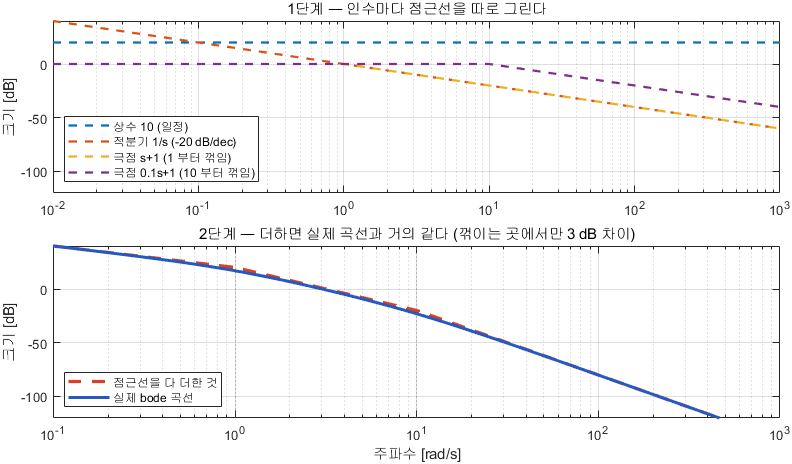

조각마다 그린 뒤 더하면 실제 곡선이 나온다

**그림 파일** `w09_asymptote.png` — `make_figures.m` 의 `fig_bode_asymptote` · 다시 만들려면 `make_figures('w09_asymptote')`

**만드는 곳** — `make_figures.m` 의 `fig_bode_asymptote` **직접 해 보려면** — `W09_02_bode_asymptotes.m` 을 절 단위로 실행하면 조각을 하나씩 얹는 과정을 볼 수 있습니다

그림 해석 — **위 칸에서 조각을 세고, 아래 칸에서 합계를 확인합니다**

**곱셈이 덧셈이 되는 것**이 로그를 쓰는 이유입니다. $G_1 G_2$ 의 dB 값은 $G_1$ 의 dB 와 $G_2$ 의 dB 를 더한 것입니다.

읽을 것

- 꺾임주파수 **밖에서는 점근선이 거의 정확**하다

- 꺾임주파수 **에서만 약 **$3$** dB 어긋난다**

- 그 이유는 1차 극점이 꺾임주파수에서 정확히 $-3.01$ dB 이기 때문이다 ($|1/(j1+1)| = 1/\sqrt{2}$)

L = 10/(s*(s+1)*(0.1*s+1));
w = logspace(-2, 3, 600);
a_sum = 20*log10(10) - 20*log10(w) ...
        - 20*log10(max(w/1,1)) - 20*log10(max(w/10,1));
m_real = 20*log10(squeeze(abs(freqresp(L, w))));
semilogx(w, a_sum, '--', 'LineWidth', 2.5); hold on; grid on;
semilogx(w, m_real, 'LineWidth', 2);
xline(1, ':'); xline(10, ':');
xlabel('주파수 [rad s^{-1}]'); ylabel('크기 [dB]'); ylim([-120 40]);
legend('점근선의 합', '실제 곡선', 'Location','southwest');
title('점근선을 더하면 실제와 거의 같다');
fprintf('=== 점근선과 실제의 차이 ===\n');
fprintf('     w[rad s^-1]   점근선[dB]   실제[dB]   차이[dB]\n');
fprintf('    ------------  -----------  ---------  ---------\n');
for wq = [0.1 1 2 10 100]
    fprintf('    %12.2f  %11.2f  %9.2f  %9.2f\n', wq, ...
            interp1(log(w), a_sum, log(wq)), ...
            interp1(log(w), m_real, log(wq)), ...
            interp1(log(w), m_real, log(wq)) - interp1(log(w), a_sum, log(wq)));
end
fprintf('\n');

## 5-3. 위상도 점근선으로 그린다

앞 절에서는 **크기**만 점근선으로 그렸습니다. 그런데 10주차와 11주차에서 실제로 필요한 것은 **위상**입니다. 위상여유가 거기서 나오기 때문입니다. 위상 점근선 규칙을 세웁니다.

크기는 꺾임주파수에서 딱 꺾이지만, **위상은 그렇게 급하게 안 변합니다.** 그래서 규칙이 조금 다릅니다.

**외울 것은 두 가지뿐입니다.**

- 변화는 꺾임주파수의 $1/10$** 에서 시작해 **$10$** 배에서 끝난다** (두 데케이드)

- 꺾임주파수 **바로 그 자리에서 정확히 절반**, 즉 $-45^\circ$

왜 두 데케이드인가 — 1차 극점의 위상은 $-\arctan(\omega/\omega_c)$ 이고, $\omega = 0.1\omega_c$ 에서 $-5.7^\circ$, $\omega = 10\omega_c$ 에서 $-84.3^\circ$ 입니다. 양 끝에서 $0^\circ$ 와 $-90^\circ$ 에 충분히 가까워지므로 그 구간만 직선으로 잇습니다.

앞 절과 같은 $L(s) = \frac{10}{s(s+1)(0.1s+1)}$ 로 그려 봅니다.

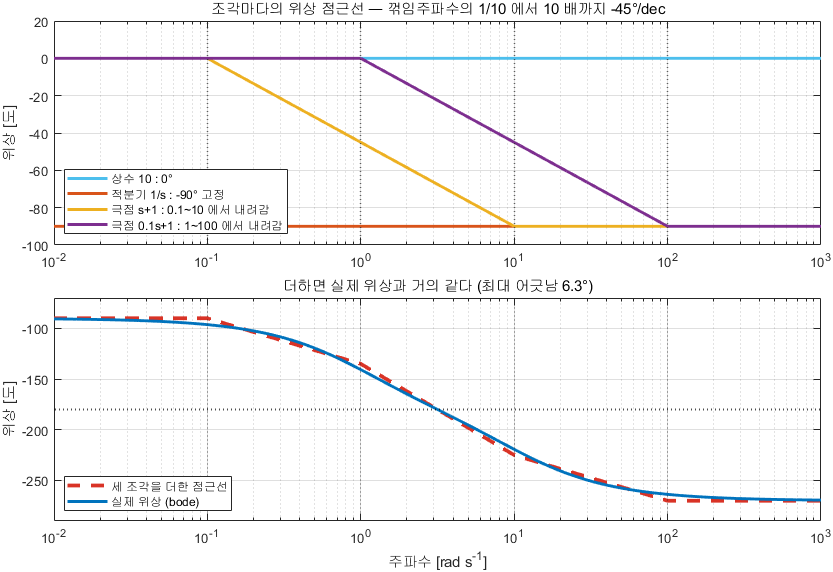

위상도 조각을 더하면 실제와 거의 같다

**그림 파일** `w09_phase_asym.png` — `make_figures.m` 의 `fig_w09_phase_asym` · 다시 만들려면 `make_figures('w09_phase_asym')`

**만드는 곳** — `make_figures.m` 의 `fig_w09_phase_asym` **직접 확인해 보려면** — 아래 코드가 같은 표를 숫자로 찍어 줍니다

그림 해석

아래 표에서 어긋남을 숫자로 확인하십시오.

L5 = 10/(s*(s+1)*(0.1*s+1));
fprintf('=== 위상 점근선과 실제 ===\n');
fprintf('  %-10s %-10s %-10s %-10s %s\n', 'w', '적분기', '두 극점', '점근선 합', '실제[도]');
for wq = [0.1 0.316 1 3.162 10 31.6 100]
    pa1 = -45*min(max(log10(wq/0.1), 0), 2);      % 극점 s+1  (꺾임 1)
    pa2 = -45*min(max(log10(wq/1  ), 0), 2);      % 극점 0.1s+1 (꺾임 10)
    pas = -90 + pa1 + pa2;
    [~, pt] = bode(L5, wq);
    fprintf('  %-10.3f %-10.0f %-10.1f %-10.2f %.2f   (차이 %+.2f)\n', ...
            wq, -90, pa1+pa2, pas, squeeze(pt), squeeze(pt) - pas);
end
fprintf('  --> 어긋남이 최대 6.3 도. 설계 초안에는 충분합니다.\n\n');

## 5-4. 점근선만으로 교차주파수와 위상여유를 읽는다

**이 절이 손작도를 배우는 이유입니다.** 지금까지 그린 두 점근선만 있으면 다음 두 숫자를 컴퓨터 없이 얻습니다.

- **교차주파수** $\omega_c$ — 크기 점근선이 $0$ dB 를 지나는 곳

- **위상여유** $PM$ — 그 자리에서 위상을 읽고 $180^\circ$ 를 더한 값

두 숫자가 10주차와 11주차의 전부입니다.

우리 예제로 해 봅니다. 크기 점근선은 $1 < \omega < 10$ 구간에서


$$20\log_{10}10 - 20\log_{10}\omega - 20\log_{10}\omega = 20 - 40\log_{10}\omega$$


이것이 $0$ 이 되는 곳은 $\log_{10}\omega = 0.5$, 즉 $\omega_c = \sqrt{10} = 3.16$ 입니다. (구한 값이 정말 $1 \sim 10$ 안에 있는지 **반드시 확인**하십시오. 다른 구간의 식을 썼다면 답이 그 구간 밖으로 나옵니다.)

그 자리에서 위상 점근선을 읽으면


$$-90^\circ - 45^\circ\log_{10}\frac{3.16}{0.1} - 45^\circ\log_{10}\frac{3.16}{1} = -90^\circ - 67.5^\circ - 22.5^\circ = -180^\circ$$


따라서 $PM = 180^\circ - 180^\circ = 0^\circ$ 입니다. **이 루프는 거의 불안정합니다.**

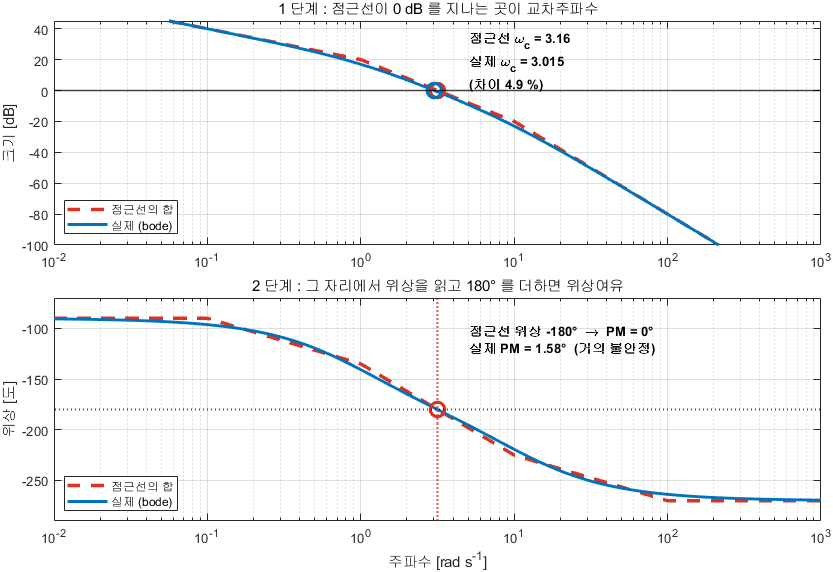

점근선 두 장으로 교차주파수와 위상여유를 읽는다

**그림 파일** `w09_hand_margin.png` — `make_figures.m` 의 `fig_w09_hand_margin` · 다시 만들려면 `make_figures('w09_hand_margin')`

**만드는 곳** — `make_figures.m` 의 `fig_w09_hand_margin` **직접 확인해 보려면** — 아래 코드가 `margin` 으로 검산합니다

그림 해석

손으로 그린 것과 `margin` 이 준 것이 **같은 결론을 냅니다.** 이것이 손작도를 배우는 이유입니다. 플랜트를 잘못 입력했거나 부호를 틀렸을 때, 손으로 어림잡을 수 있으면 이상한 결과를 그대로 믿지 않게 됩니다.

w_hand  = 10^0.5;
ph_hand = -90 - 45*log10(w_hand/0.1) - 45*log10(w_hand/1);
[~, pm_true, ~, wc_true] = margin(L5);
fprintf('=== 손으로 읽은 값과 margin 대조 ===\n');
fprintf('  교차주파수 : 손 %.3f  vs  margin %.3f rad/s   (차이 %.1f %%)\n', ...
        w_hand, wc_true, 100*abs(w_hand-wc_true)/wc_true);
fprintf('  위상여유   : 손 %.1f 도  vs  margin %.2f 도\n', 180+ph_hand, pm_true);
fprintf('  --> 둘 다 "여유가 거의 없다" 는 같은 결론을 줍니다.\n');
fprintf('      실제로 이 루프의 계단응답은 오래 진동합니다.\n\n');

## 6. 2차 항의 봉우리

점근선만 그리면 놓치는 것이 하나 있습니다. **2차 항의 봉우리**입니다.

2차 표준형에 $s = j\omega_n$ 을 넣어 보면 실수부가 서로 상쇄되고 허수부만 남습니다.


$$T(j\omega_n) = \frac{\omega_n^2} {(j\omega_n)^2 + 2\zeta\omega_n(j\omega_n) + \omega_n^2} = \frac{\omega_n^2}{2j\zeta\omega_n^2} = \frac{1}{2j\zeta}$$


즉 $|T(j\omega_n)| = \frac{1}{2\zeta}$ 입니다. **감쇠비가 작을수록 이 값이 커집니다.** 그것이 봉우리입니다.

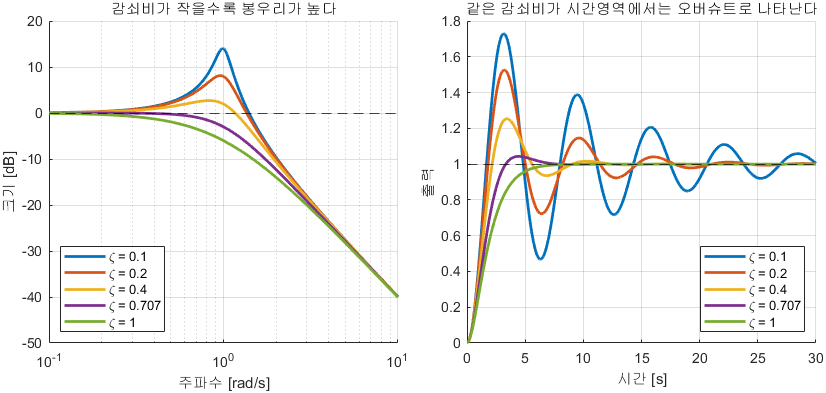

감쇠비가 작을수록 봉우리가 높고, 시간영역에서는 오버슈트가 크다

**그림 파일** `w09_resonance.png` — `make_figures.m` 의 `fig_resonance` · 다시 만들려면 `make_figures('w09_resonance')`

**만드는 곳** — `make_figures.m` 의 `fig_resonance` **직접 바꿔 보려면** — `W09_02_bode_asymptotes.m` 의 마지막 절에서 `zeta` 목록을 바꿔 실행

그림 해석 — **왼쪽 곡선과 오른쪽 곡선을 색으로 짝지어 읽으십시오**

왼쪽과 오른쪽은 **같은 사실을 두 언어로 적은 것**입니다. 주파수영역의 "봉우리" 가 시간영역의 "오버슈트" 입니다. 10주차에서 이 대응을 $\zeta \approx \mathrm{PM}/100$ 이라는 공식으로 만듭니다.

## 6-1. 봉우리와 오버슈트는 같은 이야기다

4주차에서 배운 것과 연결됩니다.

- 시간영역 : $\zeta$ 가 작으면 **오버슈트**가 크다

- 주파수영역 : $\zeta$ 가 작으면 **봉우리**가 크다

같은 성질을 두 각도에서 보는 것뿐입니다.

정확한 봉우리 값과 그 위치는 이렇습니다 ($\zeta < 0.707$ 일 때만 존재).


$$M_r = \frac{1}{2\zeta\sqrt{1-\zeta^2}}, \qquad \omega_r = \omega_n\sqrt{1 - 2\zeta^2}$$


$\zeta \ge 0.707$ 이면 봉우리가 아예 없습니다. 이 값이 실무에서 자주 쓰이는 이유입니다.

fprintf('=== 감쇠비, 봉우리, 오버슈트 ===\n');
fprintf('     zeta    봉우리 Mr[dB]   오버슈트[%%]\n');
fprintf('    ------  --------------  ------------\n');
for z = [0.1 0.2 0.3 0.5 0.707 1.0]
    Tz = 1/(s^2 + 2*z*s + 1);
    ii = stepinfo(Tz);
    if z < 1/sqrt(2) - 1e-3
        Mr = 1/(2*z*sqrt(1-z^2));
        fprintf('    %6.3f  %14.2f  %12.2f\n', z, 20*log10(Mr), ii.Overshoot);
    else
        fprintf('    %6.3f  %14s  %12.2f\n', z, '없음', ii.Overshoot);
    end
end
fprintf('\n');

## 7. 필터 — 주파수로 신호를 골라내기

지금까지는 시스템을 "제어 대상" 으로만 봤습니다. 그런데 같은 전달함수를 **신호를 골라내는 도구**로 쓸 수도 있습니다. 그것이 필터입니다.

왜 지금 필터를 다루는가 — 세 가지가 오늘 배운 것과 그대로 이어집니다.

- 필터는 **주파수마다 다르게 통과시키는 것**이다. 곧 크기 응답 그 자체다

- 무엇을 통과시키고 무엇을 막을지는 **보드 선도로 정한다**

- 그리고 **공짜가 아니다.** 막는 대신 위상이 늦는다

마지막 항목이 이 과목에서 가장 중요합니다. 7주차에서 미분항의 잡음을 잡으려고 필터를 붙였고, 11주차에서 Lead 와 Lag 를 쓸 때 같은 맞바꿈을 다시 만납니다.

## 7-1. 저역통과 필터 — 느린 것은 통과, 빠른 것은 차단

가장 많이 쓰는 필터입니다. 1차 저역통과는 이렇게 생겼습니다.


$$G(s) = \frac{1}{\tau s + 1} = \frac{\omega_0}{s + \omega_0}, \qquad \omega_0 = \frac{1}{\tau}$$


기호를 정리해 두겠습니다.

세 가지가 **같은 하나**를 다르게 부르는 것입니다. 하나를 정하면 나머지가 정해집니다.

## 7-2. 실제로 어떻게 되는가 — 네 칸으로 함께 보기

왼쪽 두 칸은 **주파수영역**, 오른쪽 두 칸은 **시간영역**입니다. 같은 필터를 두 눈으로 보는 것입니다.

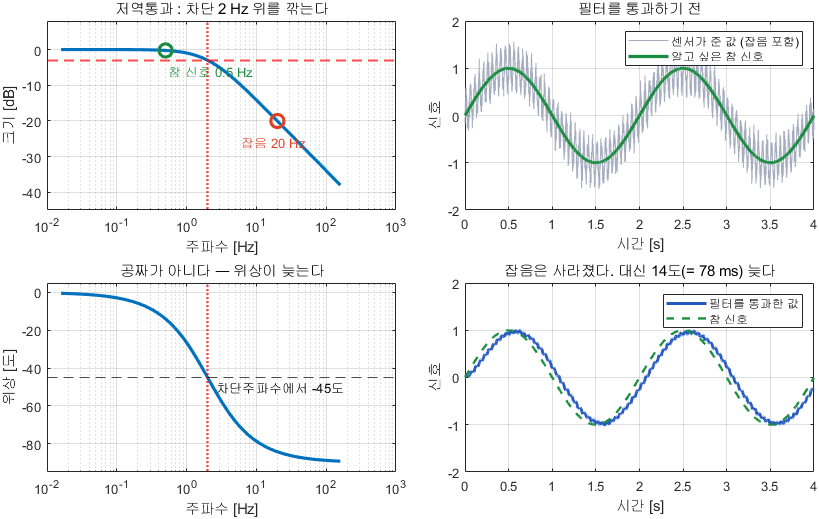

저역통과 : 왼쪽은 주파수, 오른쪽은 시간

**그림 파일** `w09_lpf.png` — `make_figures.m` 의 `fig_lpf` · 다시 만들려면 `make_figures('w09_lpf')`

**만드는 곳** — `make_figures.m` 의 `fig_lpf` **직접 바꿔 보려면** — 함수 안의 차단주파수 $2$ Hz 를 $0.8$ 이나 $5$ 로 바꾸면 네 칸이 함께 움직입니다

그림 해석 — **왼쪽 두 칸이 주파수 이야기, 오른쪽 두 칸이 시간 이야기입니다**

**공짜가 아닙니다.** 잡음을 없앤 대가로 신호가 $78$ ms 늦어졌습니다. 제어 루프 안에 필터를 넣으면 이 지연이 **위상여유를 깎습니다** (10주차). 그래서 필터는 세게 걸수록 좋은 것이 아닙니다.

왼쪽 위에서 읽을 것

- 참 신호 $0.5$ Hz 는 차단주파수($2$ Hz)보다 **아래**라 거의 그대로 지나간다 (초록 동그라미)

- 잡음 $20$ Hz 는 차단주파수보다 **위**라 $-20$ dB, 즉 **십분의 일**로 줄어든다 (빨간 동그라미)

오른쪽에서 읽을 것

- 통과 전에는 참 신호가 잡음에 덮여 있다

- 통과 후에는 잡음이 사라지고 참 신호가 드러난다

- **다만 조금 늦다.** 이것이 왼쪽 아래 위상 그림이 말해 주던 것이다

늦는 양은 계산할 수 있습니다. $0.5$ Hz 에서 위상이 $-14^\circ$ 이므로


$$\text{지연} = \frac{14^\circ}{360^\circ} \times \frac{1}{0.5\,\mathrm{Hz}} \approx 78\ \mathrm{ms}$$


## 7-3. 강의자료의 예제를 그대로

이 과목의 강의자료(부록 14쪽)에 같은 예제가 **이산 필터**로 나옵니다.


$$y(k) = a\,y(k-1) + (1-a)\,u(k), \qquad a = 0.99$$


이것은 "예전 값을 $99\%$, 새 값을 $1\%$ 씩 섞는다" 는 뜻입니다. 새 값을 조금씩만 반영하니 갑작스러운 변화(잡음)가 눌립니다.

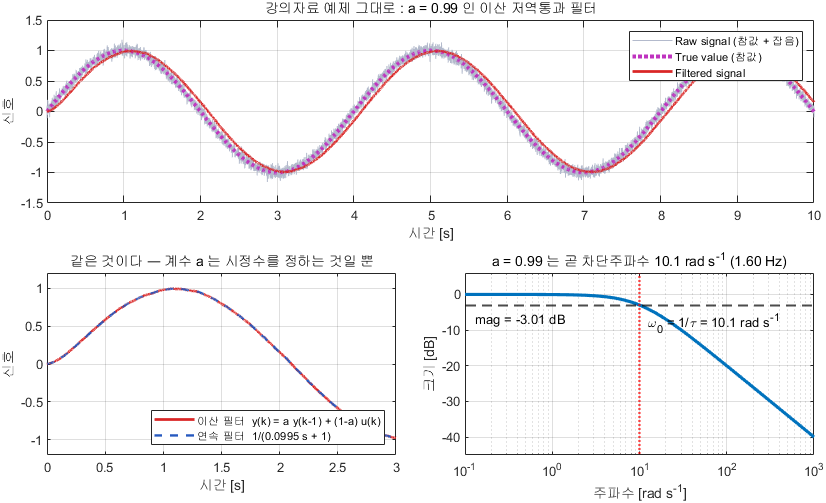

강의자료 14쪽 예제를 그대로 재현했다

**그림 파일** `w09_lpf_prof.png` — `make_figures.m` 의 `fig_lpf_prof` · 다시 만들려면 `make_figures('w09_lpf_prof')`

**만드는 곳** — `make_figures.m` 의 `fig_lpf_prof` **직접 바꿔 보려면** — 함수 안의 `a = 0.99` 를 `0.9` 나 `0.999` 로 바꾸면 세 칸이 함께 움직입니다

그림 해석

실무에서 마이크로컨트롤러에 필터를 넣을 때 쓰는 것이 아래 왼쪽의 **한 줄짜리 이산 필터**입니다. 이 강의에서 배운 $1/(\tau s + 1)$ 과 정확히 같은 것이라는 점을 확인해 두십시오.

위 칸이 강의자료의 그림입니다. `Raw signal`, `True value`, `Filtered signal` 세 개가 그대로 나옵니다. 아래 두 칸은 **오늘 배운 것과 잇기 위해** 덧붙인 것입니다.

- 왼쪽 아래 : 이 이산 필터가 사실 $1/(\tau s + 1)$ 과 **같은 것**임을 보인다

- 오른쪽 아래 : 그 필터의 보드 선도. 계수 $a$ 가 곧 차단주파수를 정한다

이산 계수 $a$ 와 시정수의 관계는 이렇습니다.


$$\tau = \frac{-\Delta t}{\ln a}$$


fprintf('=== 강의자료의 이산 필터와 연속 필터 ===\n');
dt_f = 0.001;
fprintf('     a       tau[s]    w0[rad s^-1]   f0[Hz]\n');
fprintf('   ------  ---------  -------------  --------\n');
for a_f = [0.90 0.95 0.99 0.999]
    tau_f = -dt_f/log(a_f);
    fprintf('   %6.3f  %9.5f  %13.2f  %8.3f\n', ...
            a_f, tau_f, 1/tau_f, 1/(2*pi*tau_f));
end
fprintf('\n');
fprintf('  읽는 법\n');
fprintf('    a 를 1 에 가깝게 할수록 시정수가 커집니다 = 더 매끄럽고 더 늦습니다.\n');
fprintf('    a = 0.99 는 차단주파수 1.6 Hz 짜리 필터입니다.\n');
fprintf('    같은 a 라도 **샘플 주기가 다르면 다른 필터**가 됩니다. 반드시 dt 와 함께 적으십시오.\n\n');

## 7-4. 시정수를 눈으로 읽는 법

강의자료 17쪽의 그림입니다. 계단을 넣고 $\tau$ 를 바꿔 가며 본 것입니다.

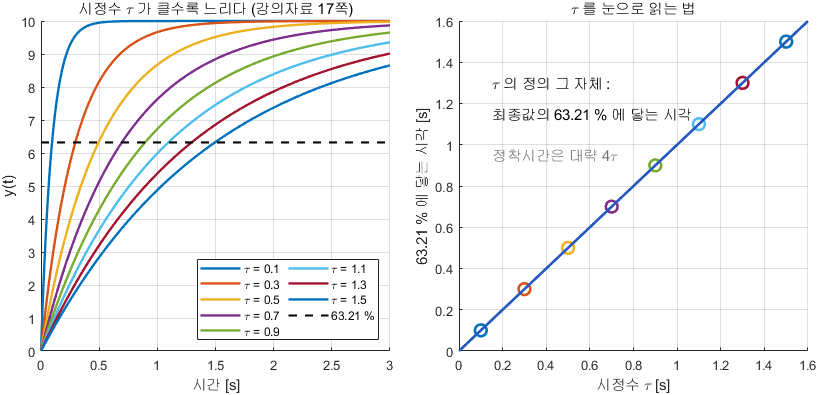

시정수가 클수록 느리다 (강의자료 17쪽)

**그림 파일** `w09_tau_time.png` — `make_figures.m` 의 `fig_tau_time` · 다시 만들려면 `make_figures('w09_tau_time')`

**만드는 곳** — `make_figures.m` 의 `fig_tau_time` **직접 바꿔 보려면** — 함수 안의 `taus` 목록에 $2.0$ 을 추가해 보십시오

그림 해석

실험 데이터에서 $\tau$ 를 읽는 법이 여기 있습니다. **최종값의 **$63\%$** 에 닿는 시각을 자로 재면 그것이 **$\tau$** 입니다.** 모델을 몰라도 됩니다.

$\tau$ 의 정의는 이것입니다.

**최종값의 **$63.21\%$** 에 닿는 시각.**

왜 하필 $63.21\%$ 인가 — 1차 계단응답이 $y(t) = y_c(1 - e^{-t/\tau})$ 이므로 $t = \tau$ 를 넣으면


$$y(\tau) = y_c\left(1 - e^{-1}\right) = 0.6321\,y_c$$


4주차에서 배운 것과 같은 이야기입니다. 정착시간은 대략 $4\tau$ 입니다.

## 7-5. 같은 것을 주파수로 보면

강의자료 19쪽의 그림입니다. 같은 $\tau$ 들을 주파수영역에서 본 것입니다.

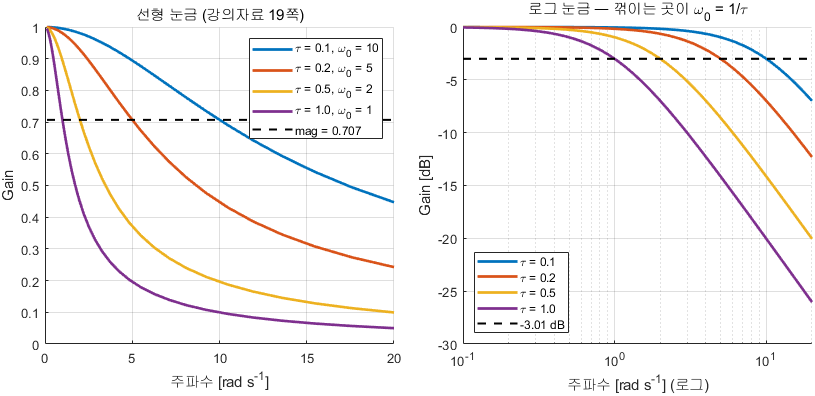

시정수별 주파수응답 (강의자료 19쪽)

**그림 파일** `w09_tau_freq.png` — `make_figures.m` 의 `fig_tau_freq` · 다시 만들려면 `make_figures('w09_tau_freq')`

**만드는 곳** — `make_figures.m` 의 `fig_tau_freq` **직접 바꿔 보려면** — 앞 그림 `fig_tau_time` 과 같은 `taus` 를 쓰므로 둘을 함께 바꿔 보면 대응이 분명해집니다

그림 해석 — **같은 내용을 선형 눈금과 로그 눈금으로 두 번 그린 것입니다**

앞 그림(시간)과 이 그림(주파수)은 **같은 **$\tau$** 를 두 방향에서 본 것**입니다. $\tau$ 가 작으면 시간영역에서는 빨리 오르고, 주파수영역에서는 넓게 통과시킵니다.

왼쪽은 선형 눈금이라 $0.707$ 선을, 오른쪽은 로그 눈금이라 $-3.01$ dB 선을 그었습니다. **같은 선입니다.**


$$20\log_{10} \frac{1}{\sqrt{2}} = 20\log_{10} 0.7071 = -3.01\ \mathrm{dB}$$


그리고 그 선을 지나는 자리가 $\omega_0 = 1/\tau$ 입니다.

**시간영역의 **$\tau$** 와 주파수영역의 **$\omega_0$** 는 같은 숫자의 앞뒷면입니다.** $\tau$ 를 두 배로 하면 $\omega_0$ 가 절반이 되고, 응답은 두 배 느려집니다.

fprintf('=== 시정수와 차단주파수는 같은 것의 앞뒷면 ===\n');
s_f = tf('s');
fprintf('     tau[s]   w0=1/tau   4*tau(정착)   실제 정착시간[s]   실제 대역폭\n');
fprintf('   --------  ---------  -----------  ----------------  -----------\n');
for tau_f = [0.1 0.2 0.5 1.0]
    Gf = 1/(tau_f*s_f + 1);
    ii = stepinfo(Gf);
    fprintf('   %8.1f  %9.1f  %11.1f  %16.2f  %11.2f\n', ...
            tau_f, 1/tau_f, 4*tau_f, ii.SettlingTime, bandwidth(Gf));
end
fprintf('   --> 4*tau 어림과 실제 정착시간이 잘 맞습니다.\n');
fprintf('       대역폭도 1/tau 와 거의 같습니다 (1차 시스템이므로).\n\n');

## 7-6. 차단주파수를 어디에 둘 것인가 — 맞바꿈

이것이 필터 설계의 전부입니다. **낮추면 조용하지만 느리고, 높이면 빠르지만 시끄럽습니다.**

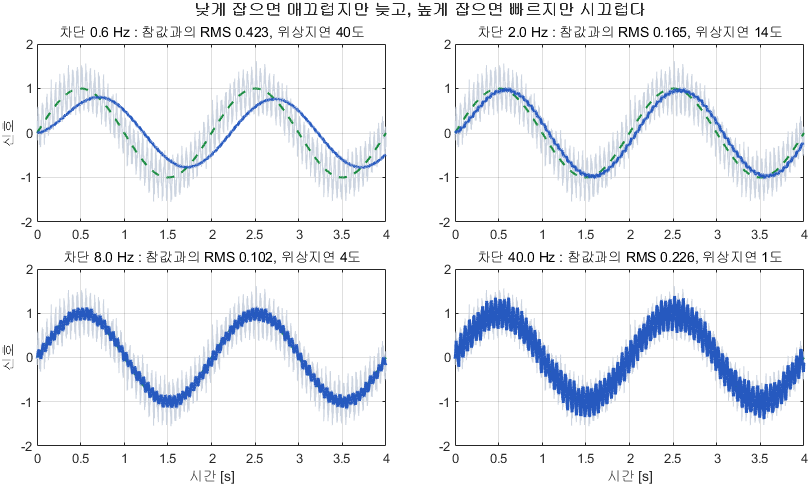

차단주파수를 바꿔 가며 같은 신호를 걸러 본 것

**그림 파일** `w09_cutoff.png` — `make_figures.m` 의 `fig_cutoff_tradeoff` · 다시 만들려면 `make_figures('w09_cutoff')`

**만드는 곳** — `make_figures.m` 의 `fig_cutoff_tradeoff` **직접 바꿔 보려면** — 함수 안의 차단주파수 목록 `[0.6 2 8 40]` 을 바꿔 실행

그림 해석 — **네 칸의 제목에 있는 두 숫자를 함께 보십시오**

**양 끝이 다 나쁘고 가운데가 좋다** — 이것이 맞바꿈입니다. 낮게 잡으면 신호까지 깎이고 늦어지며, 높게 잡으면 잡음이 그대로 들어옵니다. "필터를 세게 걸면 좋다" 는 흔한 오해를 이 그림이 정면으로 반박합니다.

네 칸의 숫자를 보면 최적이 가운데 어딘가에 있습니다.

- 차단 $0.6$ Hz — 아주 매끄럽지만 참값과의 오차가 가장 크다. **너무 늦어서** 그렇다

- 차단 $8$ Hz — 이 네 개 중에서는 오차가 가장 작다

- 차단 $40$ Hz — 잡음이 거의 그대로 통과해 오차가 다시 커진다

**그림의 네 개만 보고 고르면 안 됩니다.** 아래 표처럼 촘촘히 훑어 보면 실제 최적은 그 사이($4$ Hz 근처)에 있습니다. 필터 설계도 6~7주차의 이득 선정과 똑같이 **훑어서 고르는 일**입니다.

**고르는 원칙 하나** — 참 신호의 최고 주파수보다는 위에, 잡음의 최저 주파수보다는 아래에. 둘이 겹치면 필터로는 분리할 수 없습니다. 그때는 센서를 바꾸거나 다른 정보를 함께 써야 합니다 (칼만 필터가 그 이야기입니다).

fprintf('=== 차단주파수와 오차 ===\n');
t_f2 = (0:0.001:4)';
clean_f = sin(2*pi*0.5*t_f2);
rng(11);
noisy_f = clean_f + 0.35*sin(2*pi*20*t_f2) + 0.12*randn(size(t_f2));
fprintf('     차단[Hz]   참값과의 RMS 오차   0.5 Hz 에서의 지연[도]\n');
fprintf('   ---------  ------------------  ----------------------\n');
best_e = inf; best_f = NaN;
for fc_f = [0.3 0.6 1 2 4 8 16 40]
    Gf = (2*pi*fc_f)/(s_f + 2*pi*fc_f);
    yf = lsim(Gf, noisy_f, t_f2);
    e  = sqrt(mean((yf - clean_f).^2));
    if e < best_e, best_e = e; best_f = fc_f; end
    fprintf('   %9.1f  %18.4f  %22.1f\n', ...
            fc_f, e, -rad2deg(angle(freqresp(Gf, 2*pi*0.5))));
end
fprintf('   --> 이 신호에서는 차단 %.0f Hz 근처가 가장 좋습니다 (RMS %.4f).\n\n', ...
        best_f, best_e);

## 7-7. 고역통과 필터 — 반대로 하면

같은 자리에 $s$ 를 올려놓으면 반대가 됩니다.


$$G(s) = \frac{s}{s + \omega_0}$$


느린 것은 막고 빠른 것을 통과시킵니다. 어디에 쓰는가 — **센서의 영점이 서서히 흐르는 것(drift)을 없앨 때** 씁니다.

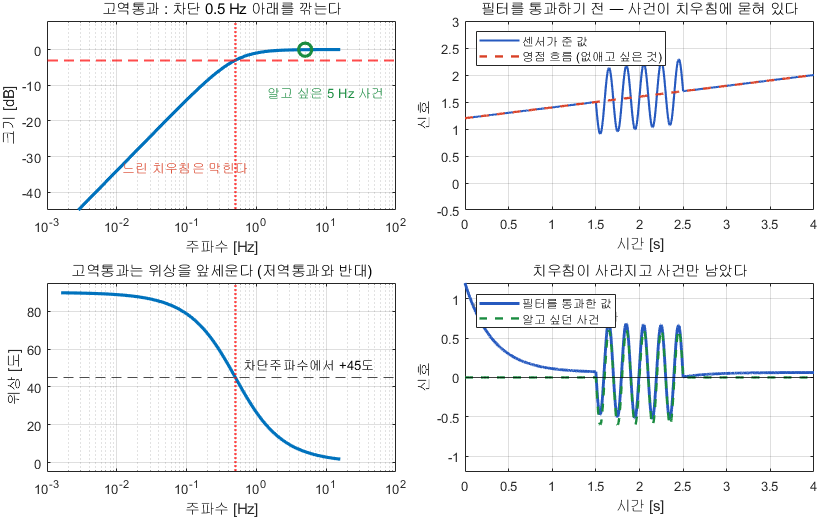

고역통과 : 느린 치우침을 걷어내고 빠른 사건만 남긴다

**그림 파일** `w09_hpf.png` — `make_figures.m` 의 `fig_hpf` · 다시 만들려면 `make_figures('w09_hpf')`

**만드는 곳** — `make_figures.m` 의 `fig_hpf` **직접 바꿔 보려면** — 함수 안의 차단주파수 $0.5$ Hz 를 $2$ 로 올리면 사건까지 함께 깎여 나갑니다

그림 해석 — **저역통과 그림과 좌우가 반대라는 점을 보십시오**

실무 용도가 분명합니다 — **가속도계나 자이로의 드리프트 제거**, 진동 신호에서 사건 검출, 심전도의 기저선 제거 등입니다. 저역통과가 "잡음 제거" 라면 고역통과는 "치우침 제거" 입니다.

읽을 것

- 원래 신호에는 서서히 올라가는 치우침이 있어 **사건이 묻혀 있다**

- 고역통과를 지나면 치우침이 사라지고 사건만 남는다

- 위상이 $+$ 쪽이다. 저역통과가 늦추는 것과 반대로 **앞세운다**

위상을 앞세운다는 것이 어디서 본 이야기 같다면 맞습니다. **미분기가 하는 일이 이것이고, 7주차의 PD 와 11주차의 Lead 가 같은 계열입니다.**


$$\frac{s}{s+\omega_0} \quad\text{와}\quad \frac{K_d\,s}{s/N + 1} \quad\text{는 같은 모양이다}$$


## 7-8. 네 가지 필터를 한눈에

저역통과·고역통과에 두 가지를 더하면 기본형이 넷입니다.

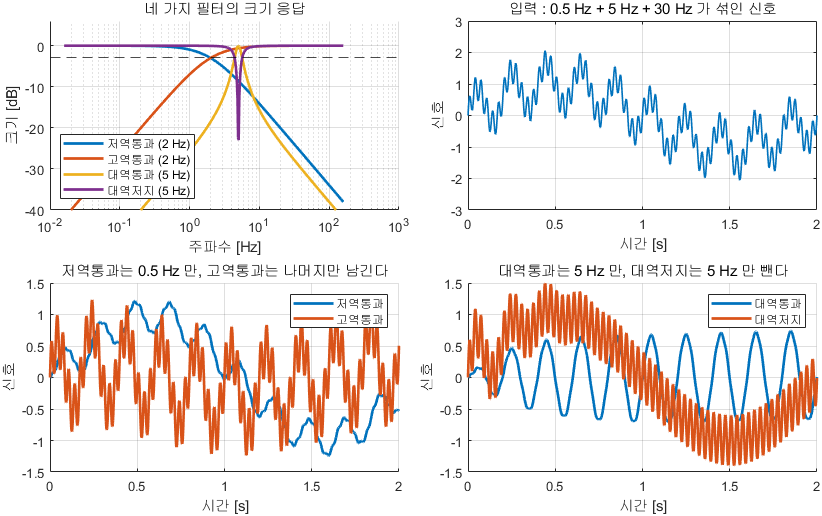

같은 신호를 네 필터에 통과시켜 본 것

**그림 파일** `w09_filters.png` — `make_figures.m` 의 `fig_filter_family` · 다시 만들려면 `make_figures('w09_filters')`

**만드는 곳** — `make_figures.m` 의 `fig_filter_family` **직접 바꿔 보려면** — 함수 안의 입력 성분 $0.5$, $5$, $30$ Hz 를 바꾸면 네 칸이 함께 달라집니다

그림 해석

필터는 **더하기와 빼기**로 만들어집니다. 대역통과 $=$ 저역통과 $\times$ 고역통과, 대역저지 $=$ 전체 $-$ 대역통과입니다.

입력은 $0.5$ Hz + $5$ Hz + $30$ Hz 세 성분이 섞인 신호입니다. 각 필터가 그중 무엇을 남기는지 시간축에서 바로 보입니다.

## 7-9. 이 과목의 플랜트도 사실 필터다

여기까지 오면 뒤집어 볼 수 있습니다. **우리가 제어하려는 대상 자체가 이미 저역통과 필터입니다.**

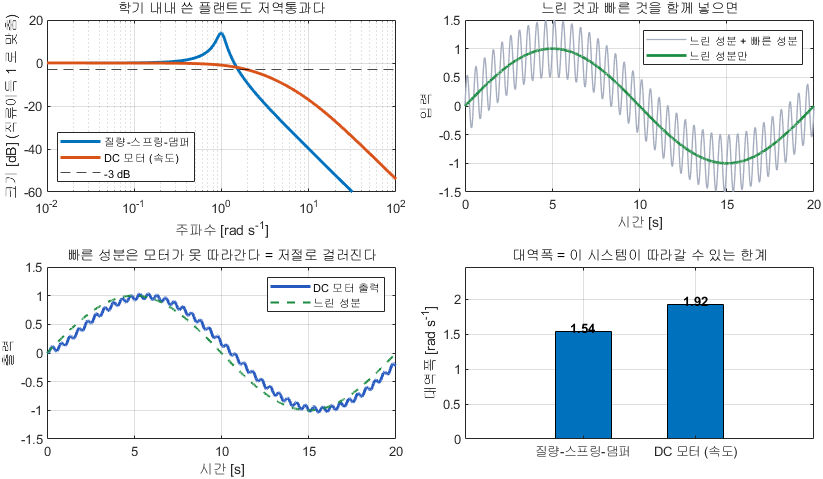

학기 내내 쓴 플랜트도 저역통과다

**그림 파일** `w09_plant_lpf.png` — `make_figures.m` 의 `fig_plant_is_lpf` · 다시 만들려면 `make_figures('w09_plant_lpf')`

**만드는 곳** — `make_figures.m` 의 `fig_plant_is_lpf` **직접 확인해 보려면** — 명령창에 `bandwidth(plant_msd())` 와 `bandwidth(plant_dcmotor('speed'))` 를 쳐 보십시오

그림 해석

**아무도 필터를 넣지 않았는데 필터처럼 동작합니다.** 물리적인 관성과 마찰 자체가 저역통과 필터이기 때문입니다. 그래서 대역폭은 "이 시스템이 따라갈 수 있는 한계" 라고 읽으면 됩니다.

물리적으로 당연합니다.

- 질량은 관성이 있어 빨리 흔들리지 않는다

- 코일은 인덕턴스가 있어 전류가 급히 바뀌지 않는다

- 열은 천천히 퍼진다

그래서 **빠른 지령은 아무리 넣어도 따라오지 못하고**, 그 한계를 숫자로 적은 것이 대역폭입니다.

다만 주의할 것이 하나 있습니다. 질량-스프링-댐퍼의 크기 곡선에는 **봉우리**가 있습니다 (감쇠비가 $0.1$ 이라서). 저역통과이긴 하지만 **차단주파수 근처를 오히려 키웁니다.** 6절에서 본 공진입니다. 필터로 쓸 생각이라면 감쇠비를 $0.707$ 이상으로 잡아야 합니다.

Gm = plant_msd();
Gd = plant_dcmotor('speed');
fprintf('=== 이 과목의 플랜트를 필터로 보면 ===\n');
fprintf('    시스템                대역폭[rad s^-1]   대역폭[Hz]   봉우리\n');
fprintf('   ------------------  -----------------  -----------  --------\n');
for c_f = {{'질량-스프링-댐퍼', Gm}, {'DC 모터 (속도)', Gd}}
    nm_f = c_f{1}{1}; G_f = c_f{1}{2};
    b_f  = bandwidth(G_f);
    w_f  = logspace(-2, 2, 2000);
    pk   = max(abs(squeeze(freqresp(G_f, w_f))))/abs(dcgain(G_f));
    if pk > 1.05, pkStr = sprintf('%.2f 배', pk); else, pkStr = '없음'; end
    fprintf('   %-18s  %17.3f  %11.3f  %8s\n', nm_f, b_f, b_f/(2*pi), pkStr);
end
fprintf('\n');
fprintf('  읽는 법\n');
fprintf('    대역폭보다 훨씬 빠른 지령은 아무리 넣어도 못 따라옵니다.\n');
fprintf('    반대로 대역폭 안쪽의 잡음은 그대로 출력에 나옵니다.\n');
fprintf('    그래서 대역폭을 넓히면 빨라지지만 잡음에 약해집니다.\n');
fprintf('    11주차에서 이 맞바꿈을 설계에 그대로 씁니다 (Lead 는 넓히고 Lag 는 좁힌다).\n\n');

## 7-10. 1차와 2차의 대역폭 — 강의자료 11~12쪽

차수가 올라가면 어떻게 되는지도 강의자료에 있습니다.

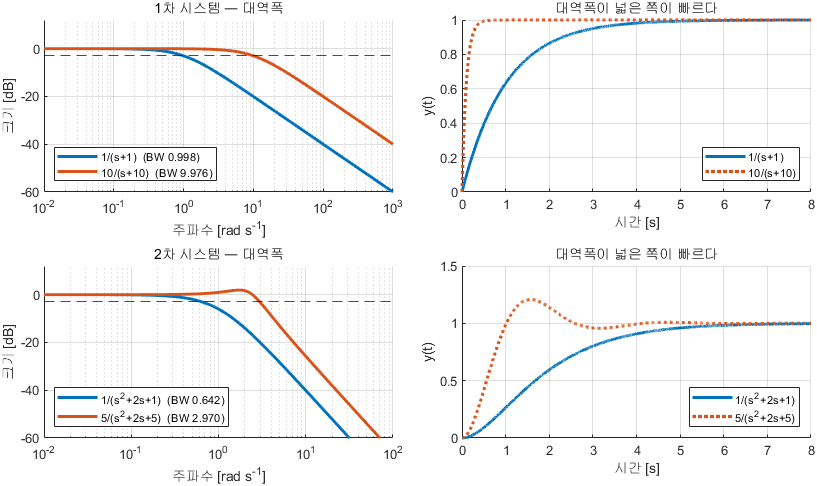

1차·2차 시스템의 대역폭과 계단응답 (강의자료 11~12쪽)

**그림 파일** `w09_bw_order.png` — `make_figures.m` 의 `fig_bw_order` · 다시 만들려면 `make_figures('w09_bw_order')`

**만드는 곳** — `make_figures.m` 의 `fig_bw_order` **직접 확인해 보려면** — 명령창에 `bandwidth(tf(10,[1 10]))` 처럼 직접 계산해 보십시오

그림 해석 — **왼쪽에서 대역폭을 읽고, 오른쪽에서 빠르기를 확인합니다**

외울 한 줄 — **대역폭이 넓으면 빠릅니다.** 어림으로는 $t_r \approx 2/\omega_{BW}$ 정도로 봅니다. 10주차에서 이 대응을 더 다룹니다.

강의자료의 숫자와 대조해 보면

fprintf('=== 강의자료 11~12쪽 숫자와 대조 ===\n');
chk = { '1/(s+1)',         tf(1,[1 1]),     0.9976
        '10/(s+10)',       tf(10,[1 10]),   9.9763
        '1/(s^2+2s+1)',    tf(1,[1 2 1]),   0.6423
        '5/(s^2+2s+5)',    tf(5,[1 2 5]),   2.9700 };
fprintf('     전달함수            계산값     강의자료     차이\n');
fprintf('   ----------------  ---------  ----------  ---------\n');
for i_f = 1:4
    b_f = bandwidth(chk{i_f,2});
    fprintf('   %-16s  %9.4f  %10.4f  %9.2e\n', ...
            chk{i_f,1}, b_f, chk{i_f,3}, abs(b_f - chk{i_f,3}));
end
fprintf('   --> 강의자료 값과 일치합니다.\n\n');
fprintf('  읽을 것\n');
fprintf('    1차는 차단 뒤 -20 dB/dec, 2차는 -40 dB/dec 로 더 가파르게 떨어집니다.\n');
fprintf('    즉 **차수가 높을수록 잘 막습니다.** 대신 위상이 더 많이 깎입니다.\n');
fprintf('    막는 능력과 위상 지연은 언제나 함께 갑니다. 공짜가 없습니다.\n\n');

## 8. Simulink 로 직접 재 보기

오늘의 마지막은 **실험**입니다. 전달함수를 모른다고 치고, 사인을 넣어 보드 선도를 만들어 봅니다.

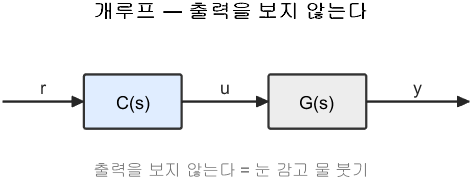

측정 대상은 열린 시스템이다

**그림 파일** `loop_open.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_open')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('open', ...)` 로 부릅니다 **직접 해 보려면** — `W09_03_run_simulink.m` 을 실행하면 `W09_SineSweep.slx` 로 이 측정을 자동으로 반복합니다

그림 해석

이 그림이 단순한 것이 핵심입니다. **모델이 없어도 잴 수 있다**는 주파수응답의 장점이 여기서 나옵니다. 실물 장비에 사인을 넣고 출력을 오실로스코프로 보면 그대로 보드 선도가 됩니다.

절차는 이렇습니다.

- 주파수를 하나 정해 사인을 넣는다

- 과도응답이 사라질 때까지 **충분히 기다린다**

- 마지막 몇 주기만 잘라 진폭비와 위상차를 계산한다

- 주파수를 바꿔 반복한다

모델을 열기 전에, 오늘 처음 보는 블록 하나를 먼저 봅니다.

`Sine Wave` — 사인파를 만드는 블록

- 하는 일 — $u(t) = A\sin(\omega t + \phi) + b$ 를 매 시각 계산해 내보낸다

- `Amplitude` — 진폭 $A$. 오늘은 $1$ 로 둔다. 선형 시스템이므로 진폭은 결과에 영향을 주지 않는다 (비율만 보기 때문)

- `Frequency` — 각주파수 $\omega$. 단위가 **Hz 가 아니라 rad/s** 다. 보드 선도의 가로축과 같은 단위이므로 그대로 넣으면 된다

- `Phase` — 시작 위상 $\phi$. 오늘은 $0$ 으로 둔다

- `Bias` — 더해지는 상수 $b$. 오늘은 $0$

- `Sample time` — $0$ 으로 두면 연속시간 신호가 된다

오늘 바꾸는 것은 `Frequency` **하나뿐입니다.** 스크립트가 이 값을 `logspace` 로 만든 목록에서 하나씩 꺼내 넣고, 그때마다 `sim` 을 부릅니다. 사람이 손으로 주파수 손잡이를 돌려 가며 재는 것과 정확히 같은 일입니다.

실습 스크립트에서 확인할 것

- `W09_01_sine_to_bode.m` — 손으로 재는 두 가지 방법과 이론값 대조

- `W09_02_bode_asymptotes.m` — 점근선 손작도

- `W09_03_run_simulink.m` — `W09_SineSweep.slx` 로 주파수를 훑어 측정

특히 마지막 스크립트에서 **짧게 돌리면 얼마나 틀리는지**를 꼭 보십시오. 감쇠비 $0.1$ 인 이 플랜트는 $8$ 초만 돌리면 $71\%$ 나 틀립니다.

## 8-1. 주파수응답을 숫자로 꺼내는 네 가지 명령

`bode` 는 그림을 그려 주지만, 설계에서는 **숫자**가 필요합니다. 한 주파수의 크기와 위상을 꺼내는 방법이 네 가지 있습니다.

**주의 두 가지**

- `bode` 의 크기 출력은 dB 가 아니라 **배수**입니다. dB 로 보려면 `mag2db` 를 씁니다

- 출력이 `1x1xN` 배열이라 그대로 `plot` 하면 오류가 납니다. `squeeze(m)` 로 폅니다

s = tf('s');
Gb = 4/(s^2 + 0.8*s + 4);
wq = [0.5 1 2 5];

[mg, ph] = bode(Gb, wq);
mg = squeeze(mg);  ph = squeeze(ph);
fprintf('%-8s %-10s %-10s %-10s\n', 'w[rad/s]', '|G| 배수', '|G| dB', '위상[도]');
for i = 1:numel(wq)
    fprintf('%-8.2f %-10.4f %-10.2f %-10.1f\n', wq(i), mg(i), mag2db(mg(i)), ph(i));
end

% 같은 값을 복소수로 직접 얻기
Gjw = evalfr(Gb, 1j*2);
fprintf('\nevalfr(G, 2j) = %.4f %+.4fi\n', real(Gjw), imag(Gjw));
fprintf('  크기 %.4f, 위상 %.1f 도  -> 위 표의 w=2 줄과 같습니다.\n', ...
        abs(Gjw), rad2deg(angle(Gjw)));
fprintf('freqresp 와의 차이 : %.2e\n', abs(freqresp(Gb,2) - Gjw));
fprintf('\n대역폭 = %.4f rad/s  (여기서 이득이 -3 dB 로 떨어집니다)\n', bandwidth(Gb));

## 9. 오늘의 정리

- 사인을 넣으면 **같은 주파수의 사인**이 나온다. 크기와 위상만 달라진다

- 그 크기비와 위상차가 곧 $G(j\omega)$ 다. $s$ 자리에 $j\omega$ 를 넣으면 끝이다

- 크기는 dB, 주파수는 로그로 그린다. **곱셈이 덧셈이 되기 때문**이다

- 전달함수는 **상수 · 적분기 · 1차 · 2차** 네 조각의 곱이고, 조각마다 점근선을 그려 더하면 전체가 된다

- 시정수 꼴 $(Ts+1)$ 로 정리하고 시작해야 한다. 상수를 빠뜨리지 말 것

- 2차 항은 $\zeta < 0.707$ 이면 봉우리가 생긴다. 대략 $1/(2\zeta)$

- 실험으로 잴 때는 **과도응답이 사라진 뒤에** 재야 한다

## 10. 다음 주 예고

오늘은 "어떻게 생겼는가" 를 봤습니다. 다음 주에는 그 그림으로 **안정도를 판단**합니다.

핵심 질문은 이것 하나입니다.

**개루프의 크기가 **$1$** 이고 위상이 **$-180^\circ$** 이면 폐루프가 불안정해진다. 그 점에서 얼마나 떨어져 있는가?**

그 거리를 **이득여유**와 **위상여유**라고 부릅니다.